CygneVideo = VideoReader("Cygne.mp4")

CygneVideo =   VideoReader with properties:

   General Properties:
            Name: 'cygne.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Cygne'
        Duration: 13.0767
     CurrentTime: 0
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 1280
          Height: 720
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



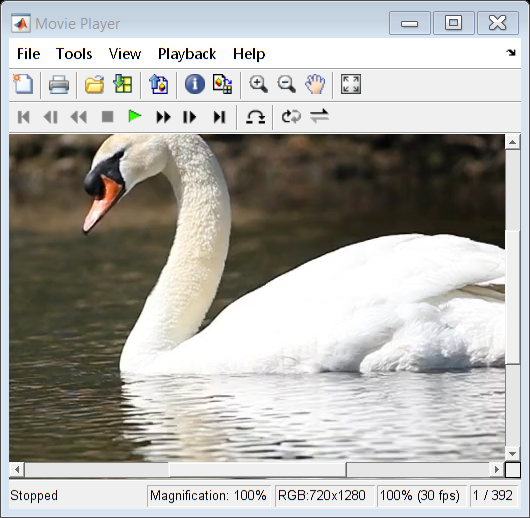

implay("Cygne.mp4")

frame_1 = read(CygneVideo,297);
frame_30 = read(CygneVideo,30);
frame_122 = read(CygneVideo,122);
frame_200 = read(CygneVideo,150);

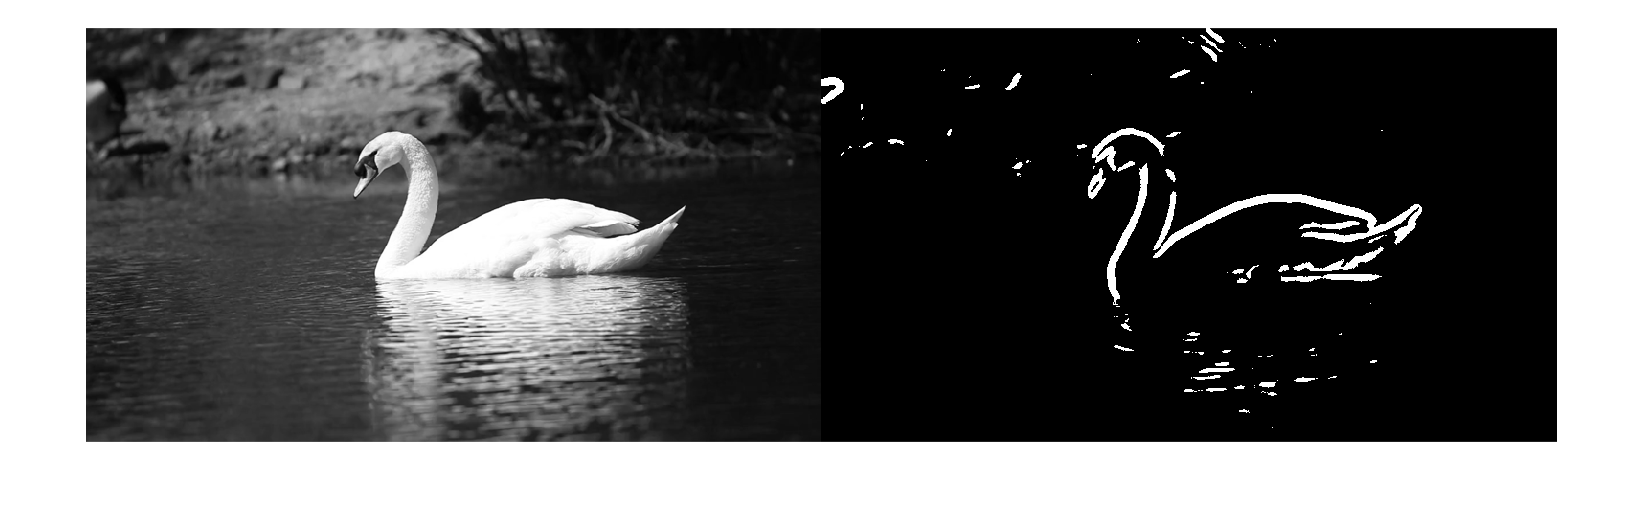

img = im2gray(imread("Cygne-001.png"));
imgFilt = imgaussfilt(img,5);
[imgEdge, threshOut, vertEdgeGrad, horzEdgeGrad] = edge(imgFilt,"roberts","nothinning");
montage({img,imgEdge})

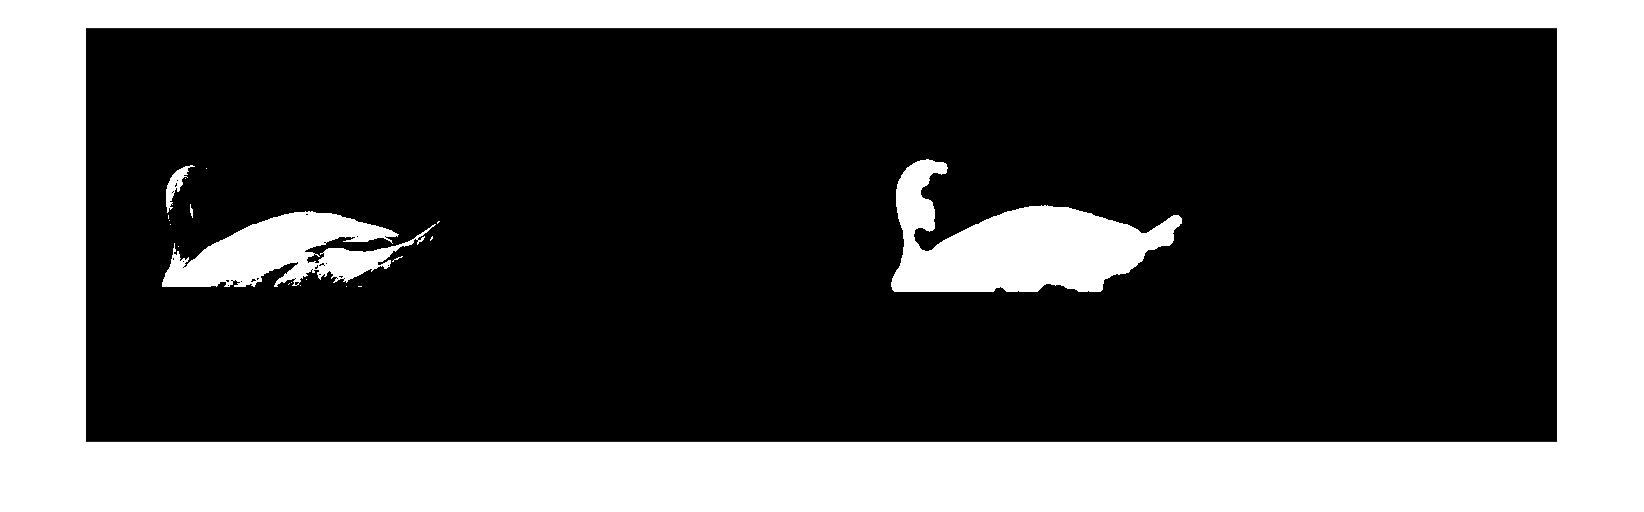

[Th,maskedRGBImage] = createMaskCygne(frame_1);
[BW,maskedImage] = segmentImageProcessedCygne(maskedRGBImage);

montage({Th,BW})


numFrames_Cygne= CygneVideo.NumFrames;
v_seg= VideoWriter("Boxed_Cygne_new","MPEG-4");

v_seg.FrameRate = CygneVideo.FrameRate;
open(v_seg);
%bboxes=[];
%idxes=[];
for i = 1 : numFrames_Cygne
    frame = read(CygneVideo,i);
    idx = string(i);
    while strlength(idx) ~= 3
        idx = append("0",idx);
    end
    %imwrite(frame,"Cygne-"+idx+".png");
    %[~,maskedRGBImage] = createMaskCygne(frame);
    %[BW,maskedImage] = segmentImageProcessedCygne(maskedRGBImage);
    
    %BW = filterRegionsCygnes(BW);
    BW = logical(imread("MaskedCygne-"+idx+".bmp"));
    props = regionprops("table",BW,"BoundingBox");
    
    BoxedCygne =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    writeVideo(v_seg, BoxedCygne);
    %bboxes = [bboxes;props];
    %idxes = [idxes;i];
    
end

coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords)

coords = 392×5 table
    frames     x1       y1       w      h 
    ______    _____    _____    ___    ___

       1      457.5    170.5    594    290
       2      457.5    170.5    594    290
       3      456.5    170.5    594    290
       4      455.5    170.5    594    290
       5      454.5    170.5    594    290
       6      453.5    170.5    594    290
       7      452.5    170.5    594    290
       8      451.5    171.5    593    289
       9      450.5    171.5    594    289
      10      450.5    171.5    593    289
      11      449.5    172.5    593    288
      12      448.5    173.5    593    287
      13      447.5    173.5    593    287
      14      446.5    173.5    593    287
      15      446.5    172.5    592    288
      16      444.5    172.5    593    288


%close(v_seg)

ans =   457.5000
  457.5000
  456.5000
  455.5000
  454.5000
  453.5000
  452.5000
  451.5000
  450.5000
  450.5000


%implay("Boxed_Cygne.mp4")
writetable(coords,"coords.txt")

frame_392=  imread("MaskedCygne-390.bmp");
frame_38 = imread("MaskedCygne-300.bmp");
frame_50 = imread("MaskedCygne-150.bmp");
